clear;
m1=-1;
m2=1;
P1=0.5;
P2=0.5;
N=1000;

var1=0.25;
var2=0.49;
var3=1.00;

x11=sqrt(var1)*randn(1,N)+m1;
x12=sqrt(var1)*randn(1,N)+m2;
x1=[x11 x12];

x21=sqrt(var2)*randn(1,N)+m1;
x22=sqrt(var2)*randn(1,N)+m2;
x2=[x21 x22];

x31=sqrt(var3)*randn(1,N)+m1;
x32=sqrt(var3)*randn(1,N)+m2;
x3=[x31 x32];

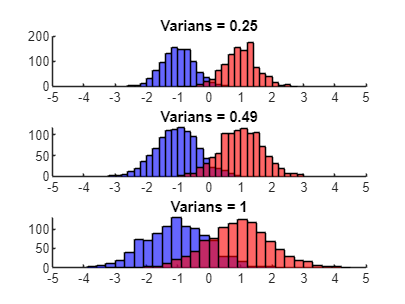

figure;
subplot(3,1,1);
hold on
histogram(x11,'FaceColor','b');
histogram(x12,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var1);

subplot(3,1,2);
hold on
histogram(x21,'FaceColor','b');
histogram(x22,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var2);

subplot(3,1,3);
hold on
histogram(x31,'FaceColor','b');
histogram(x32,'FaceColor','r');
xlim([-5 5]); xticks(-5:1:5);
title("Varians = "+var3);

% True Error rates
True_Pe1=erfc(-m1/sqrt(var1)); disp("True P_e1: "+True_Pe1);

True P_e1: 0.0046777


True_Pe2=erfc(-m1/sqrt(var2)); disp("True P_e2: "+True_Pe2);

True P_e2: 0.043352


True_Pe3=erfc(-m1/sqrt(var3)); disp("True P_e3: "+True_Pe3);

True P_e3: 0.1573


% Error rates, for different sample sizes.
N_T = [5 20 100 200];
num_experiments = 5;

% Initialize variables for confusion matrices and error rates
confusion_matrices = zeros(2, 2, num_experiments, numel(N_T));
error_rates = zeros(num_experiments, numel(N_T));
true_labels = [ones(1, N), 2 * ones(1, N)];

for exp_idx = 1:num_experiments
    for nt_idx = 1:numel(N_T)
        % Sample from combined data
        sample_indices = randperm(numel(x1), N_T(nt_idx));
        samples = x1(sample_indices);
        
        % Predict which class each sample belongs to
        predicted_labels = (abs(samples - m1) > abs(samples - m2)) + 1;
        
        % Compute confusion matrix
        confusion_matrix = confusionmat(true_labels(sample_indices), predicted_labels);
        confusion_matrices(:, :, exp_idx, nt_idx) = confusion_matrix;
        
        % Compute error rate
        % Compare true labels with predicted labels
        is_correct = (true_labels(sample_indices) == predicted_labels);
        error_rate = sum(~is_correct) / numel(is_correct);
        error_rates(exp_idx, nt_idx) = error_rate;
    end
end

% Average confusion matrices
avg_confusion_matrices = mean(confusion_matrices, 3);

% Average error rates
avg_error_rates = mean(error_rates, 1);

% Display results
disp('Averaged Confusion Matrices:');

Averaged Confusion Matrices:


disp(avg_confusion_matrices);


(:,:,1,1) =

    2.2000    0.2000
    0.6000    2.0000


(:,:,1,2) =

    9.4000         0
    0.4000   10.2000


(:,:,1,3) =

   48.0000    0.6000
    1.4000   50.0000


(:,:,1,4) =

  103.6000    1.6000
    1.8000   93.0000




disp('Averaged Error Rates:');

Averaged Error Rates:


disp(avg_error_rates);

    0.1600    0.0200    0.0200    0.0170

